# **Verify Pivit Calibration Function Using RobotStudio**

clc;clear;close all


## **Simulation Data**

**Data File Generated using ABB RobotStudio / Rapid Programming**

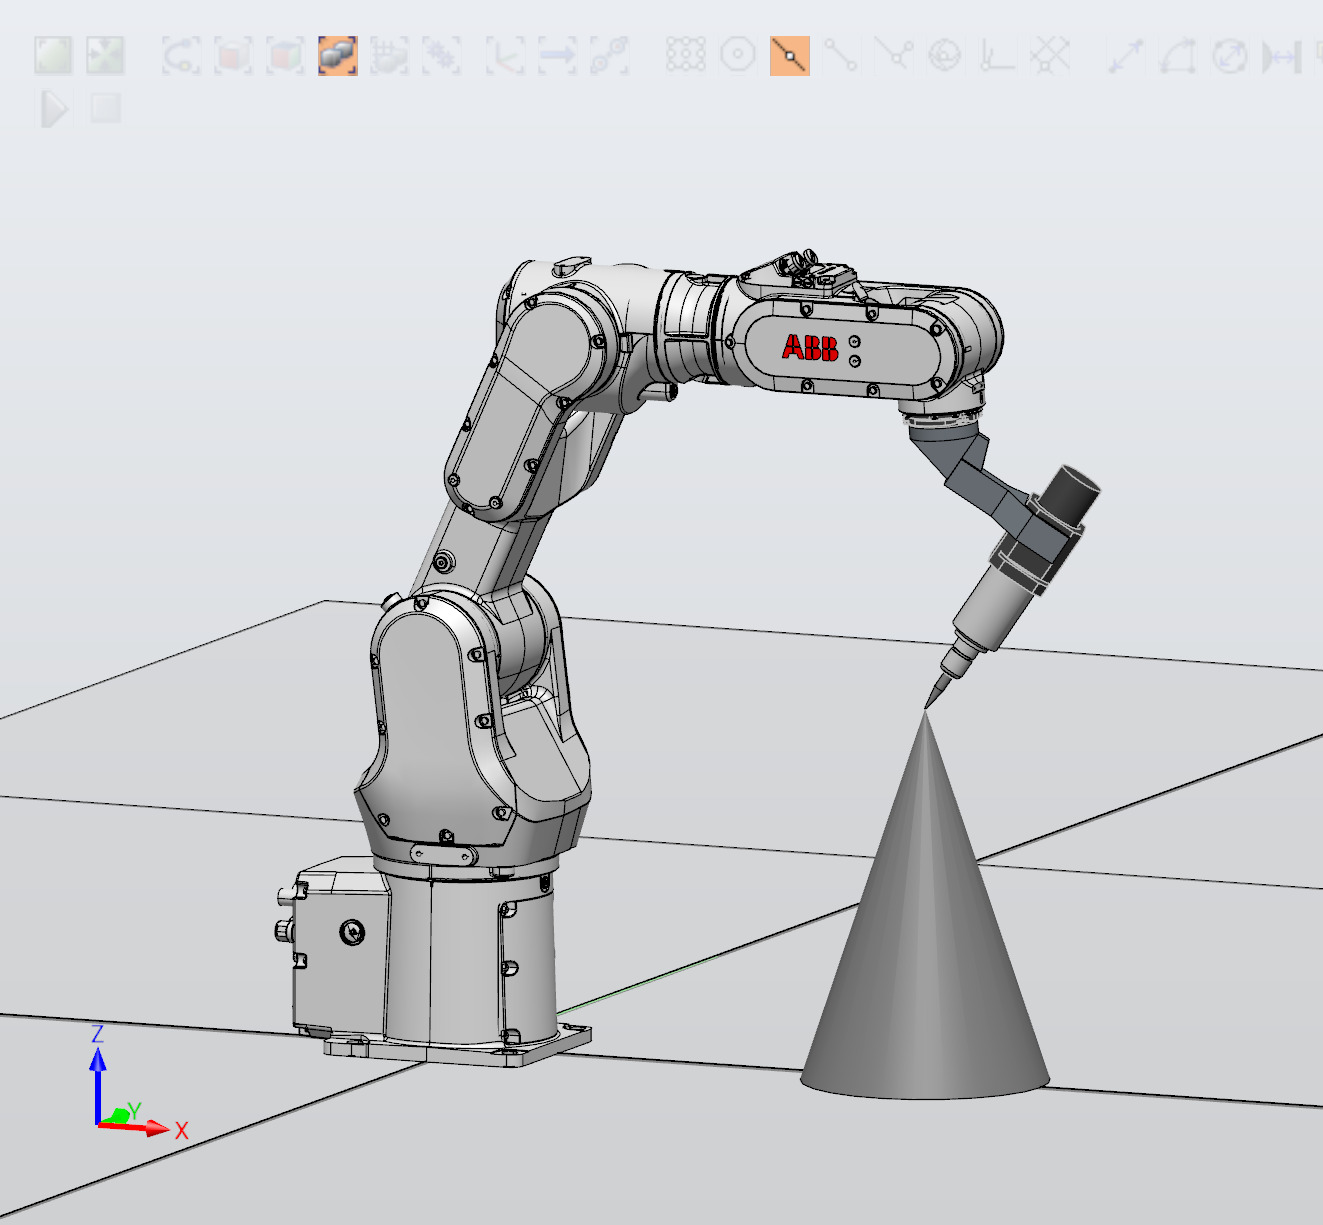 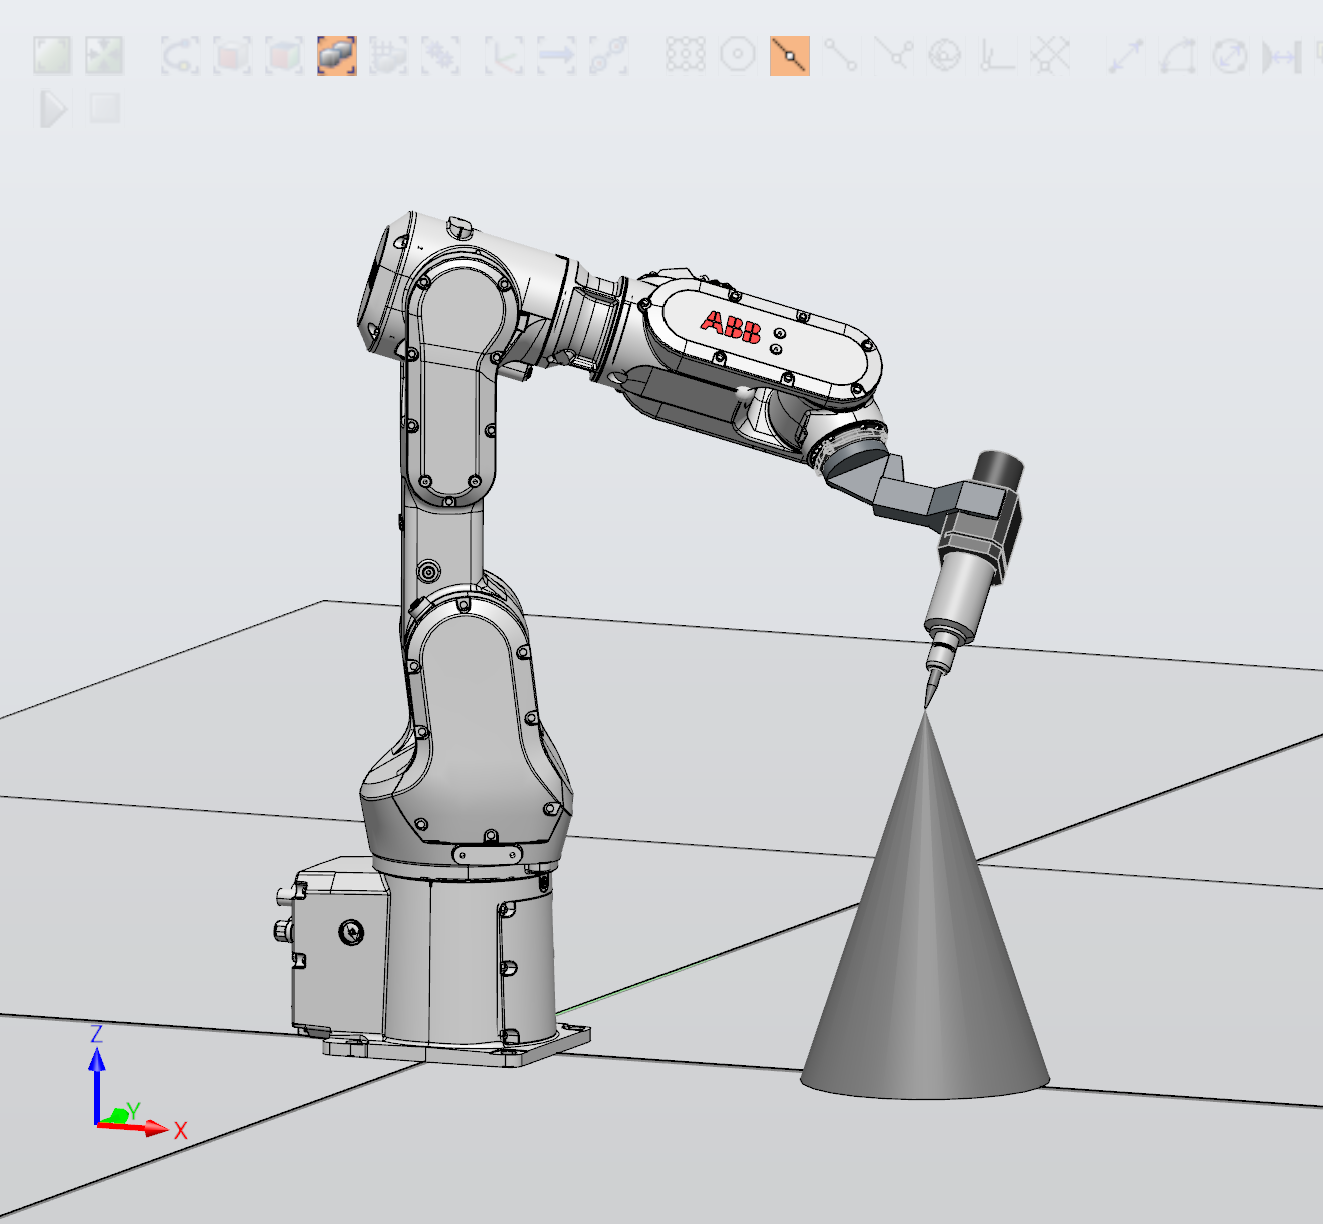

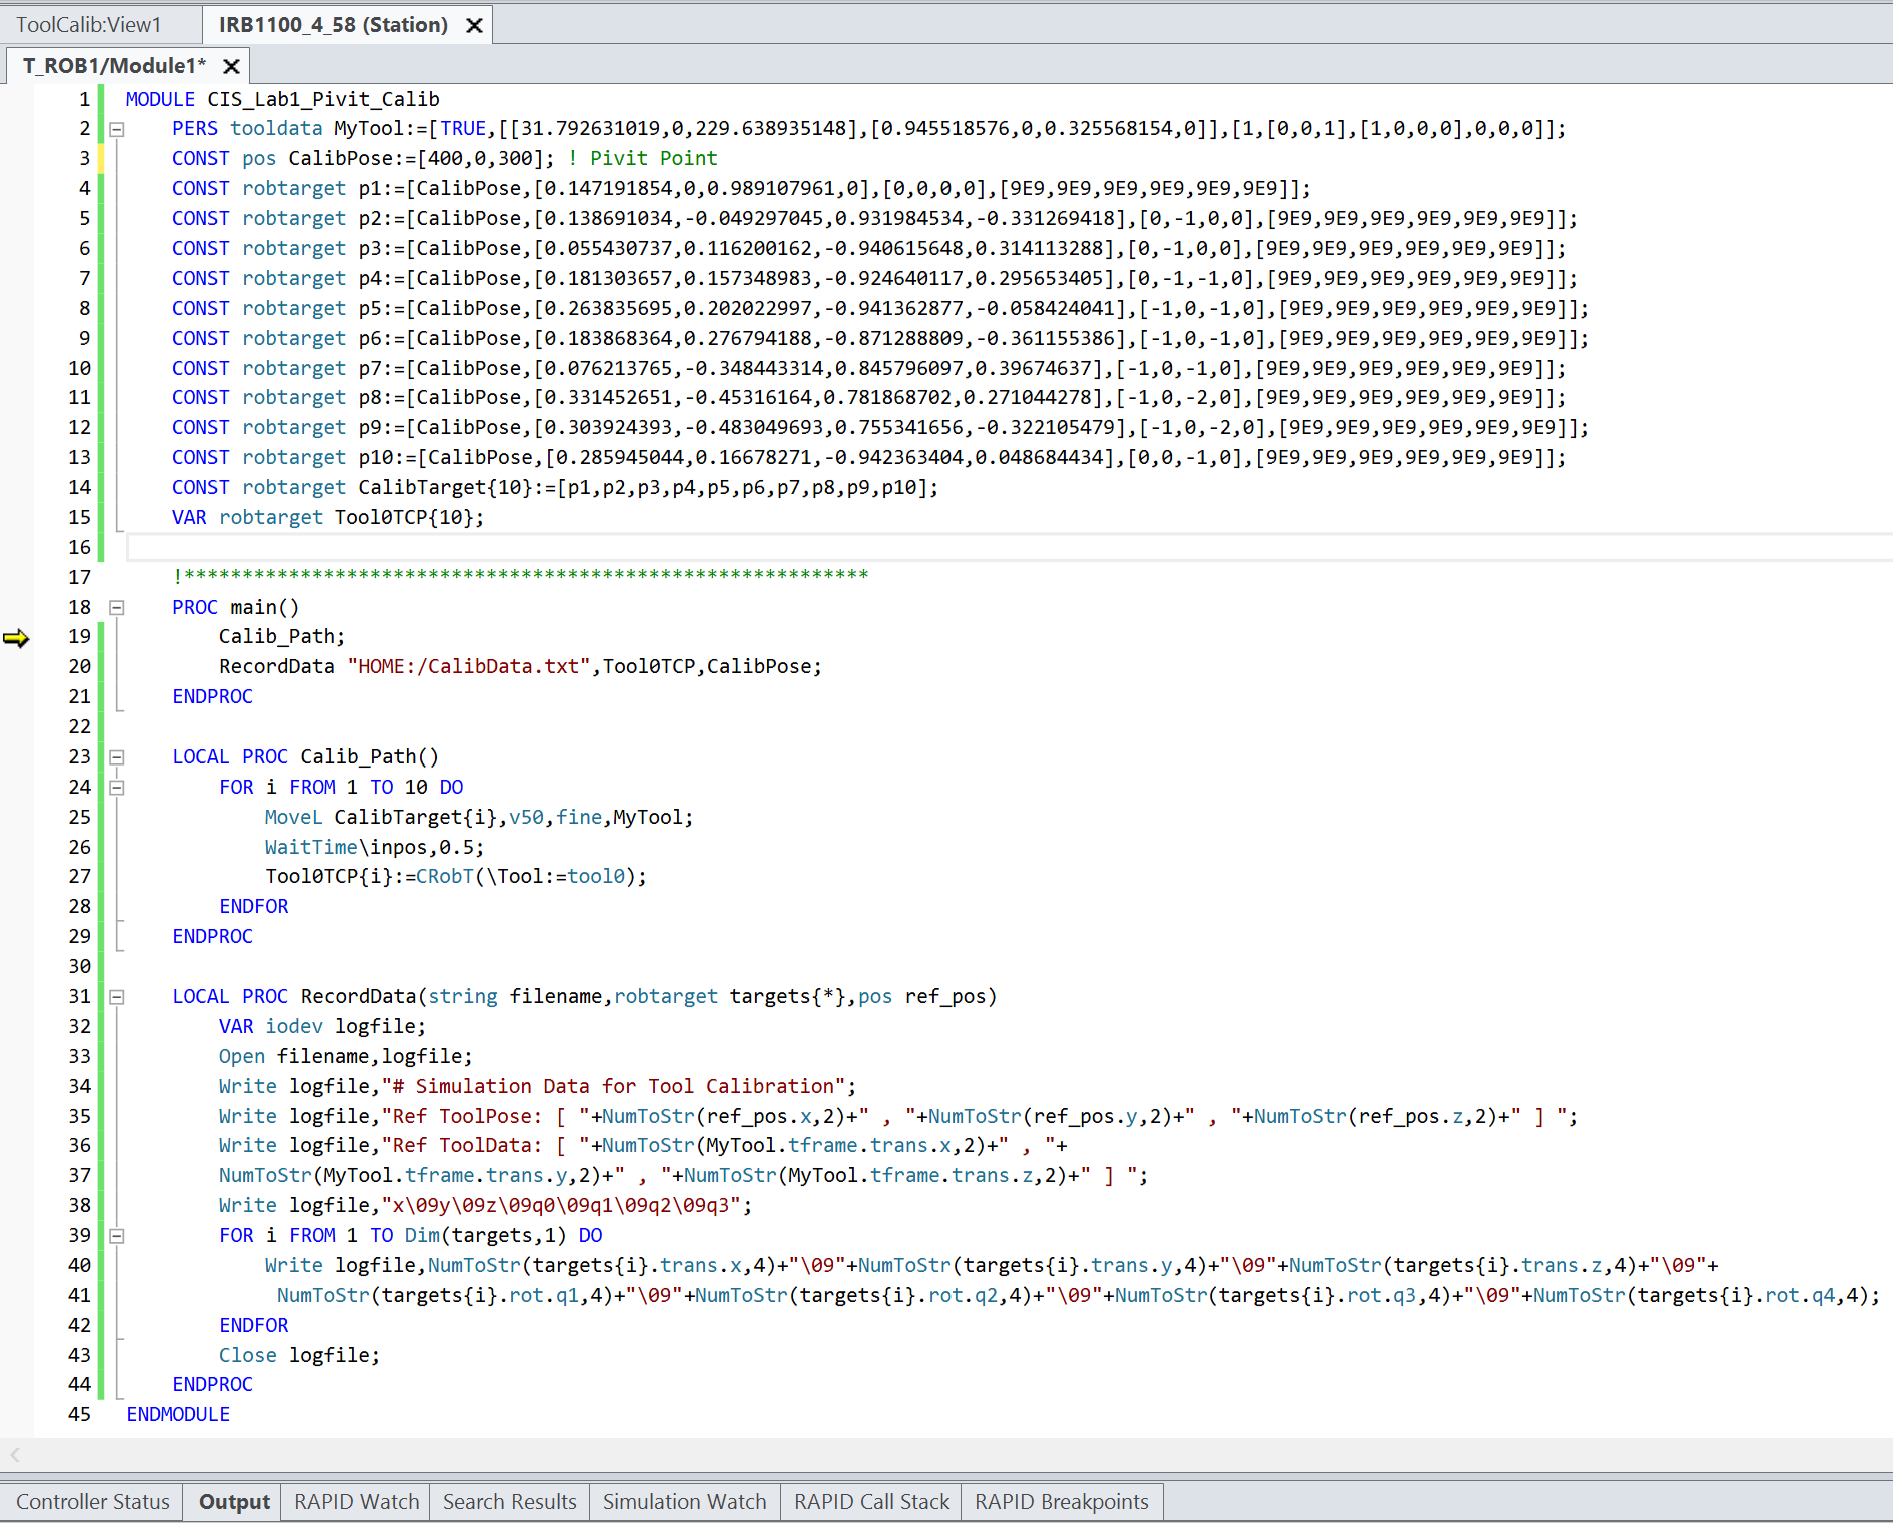

Using RobotStudio Rapid create a txt file, with Location and Orientation of the Tool Mount:

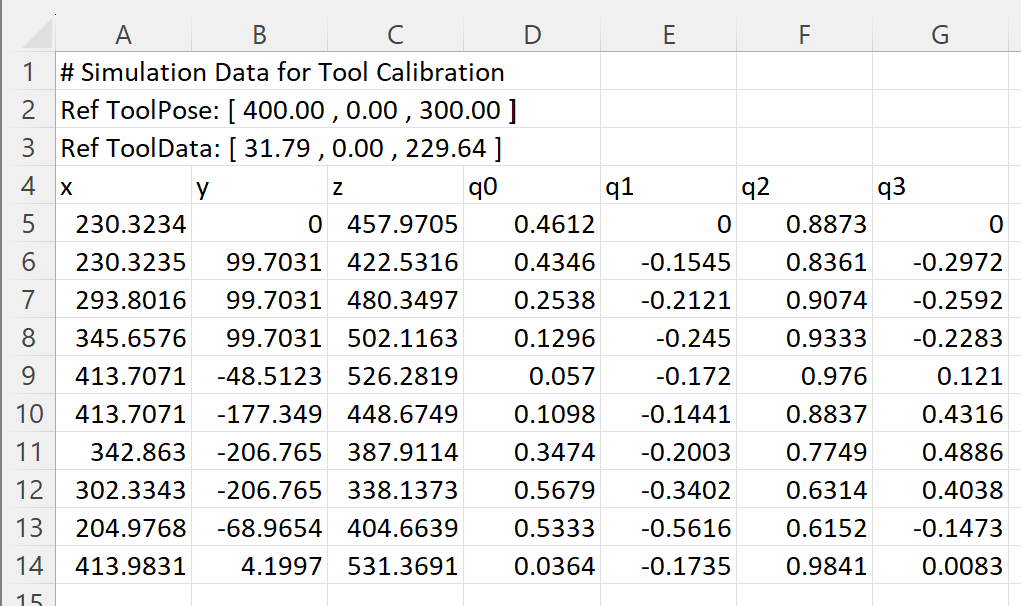

## **Prapare Data**

Get data from file generated by ABB Rapid

datastruc = importdata('CalibData.txt','\t',4);
calib_data = datastruc.data;
bpm = regexp(datastruc.textdata{2,1}, '\[([^\]]+)\]','match');
btm = regexp(datastruc.textdata{3,1}, '\[([^\]]+)\]','match');
b_post_ref = eval(bpm{1});
b_tip_ref = eval(btm{1});

Position of the Tool Mount

ptnum = size(calib_data,1);
pk = calib_data(:,1:3)';

Since Data from sensor have some round off error, rotation matrix or Quaternions may not be real "Rotation"

qk = ForceRot(calib_data(:,4:7),'q');
Rk = Q2R(qk);

### **Calibration**


$${\vec{b} }_{\textrm{post}} =F_{0~\textrm{track}} \cdot {\vec{b} }_{\textrm{track}~\textrm{tip}} =R_{0~\textrm{track}} \cdot {\vec{b} }_{\textrm{track}~\textrm{tip}} +{\vec{P} }_{0~\textrm{track}}$$



$$R_{0~\textrm{track}} \cdot {\vec{b} }_{\textrm{track}~\textrm{tip}} -{\vec{b} }_{\textrm{post}} =-{\vec{P} }_{0~\textrm{track}}$$



$$\left\lbrack \begin{array}{cc}
\vdots  & \vdots \\
R_{0~\textrm{track},\;\textrm{measure}\;k}  & -\mathrm{I}\\
\vdots  & \vdots 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\vec{b} }_{\textrm{track}~\textrm{tip}} \\
{\vec{b} }_{\textrm{post}} 
\end{array}\right\rbrack \cong \left\lbrack \begin{array}{c}
\vdots \\
-{\vec{P} }_{0~\textrm{track},\;\textrm{measure}\;k} \\
\vdots 
\end{array}\right\rbrack$$


Least Square solve for ${\vec{b} }_{\textrm{track}~\textrm{tip}}$ and ${\vec{b} }_{\textrm{post}}$

[b_tip,b_post] = ToolCalib(Rk, pk);

fprintf('Reference b_tip:  %6.2f , %6.2f , %6.2f',b_tip_ref);...
fprintf('Calibrate b_tip:  %6.2f , %6.2f , %6.2f',b_tip);...
fprintf(' ');...
fprintf('Reference b_post:  %6.2f , %6.2f , %6.2f',b_post_ref);...
fprintf('Calibrate b_post:  %6.2f , %6.2f , %6.2f',b_post)

Reference b_tip:   31.79 ,   0.00 , 229.64

Calibrate b_tip:   31.79 ,   0.00 , 229.64

Reference b_post:  400.00 ,   0.00 , 300.00

Calibrate b_post:  400.00 ,   0.00 , 300.00

## Check: Plot Frame

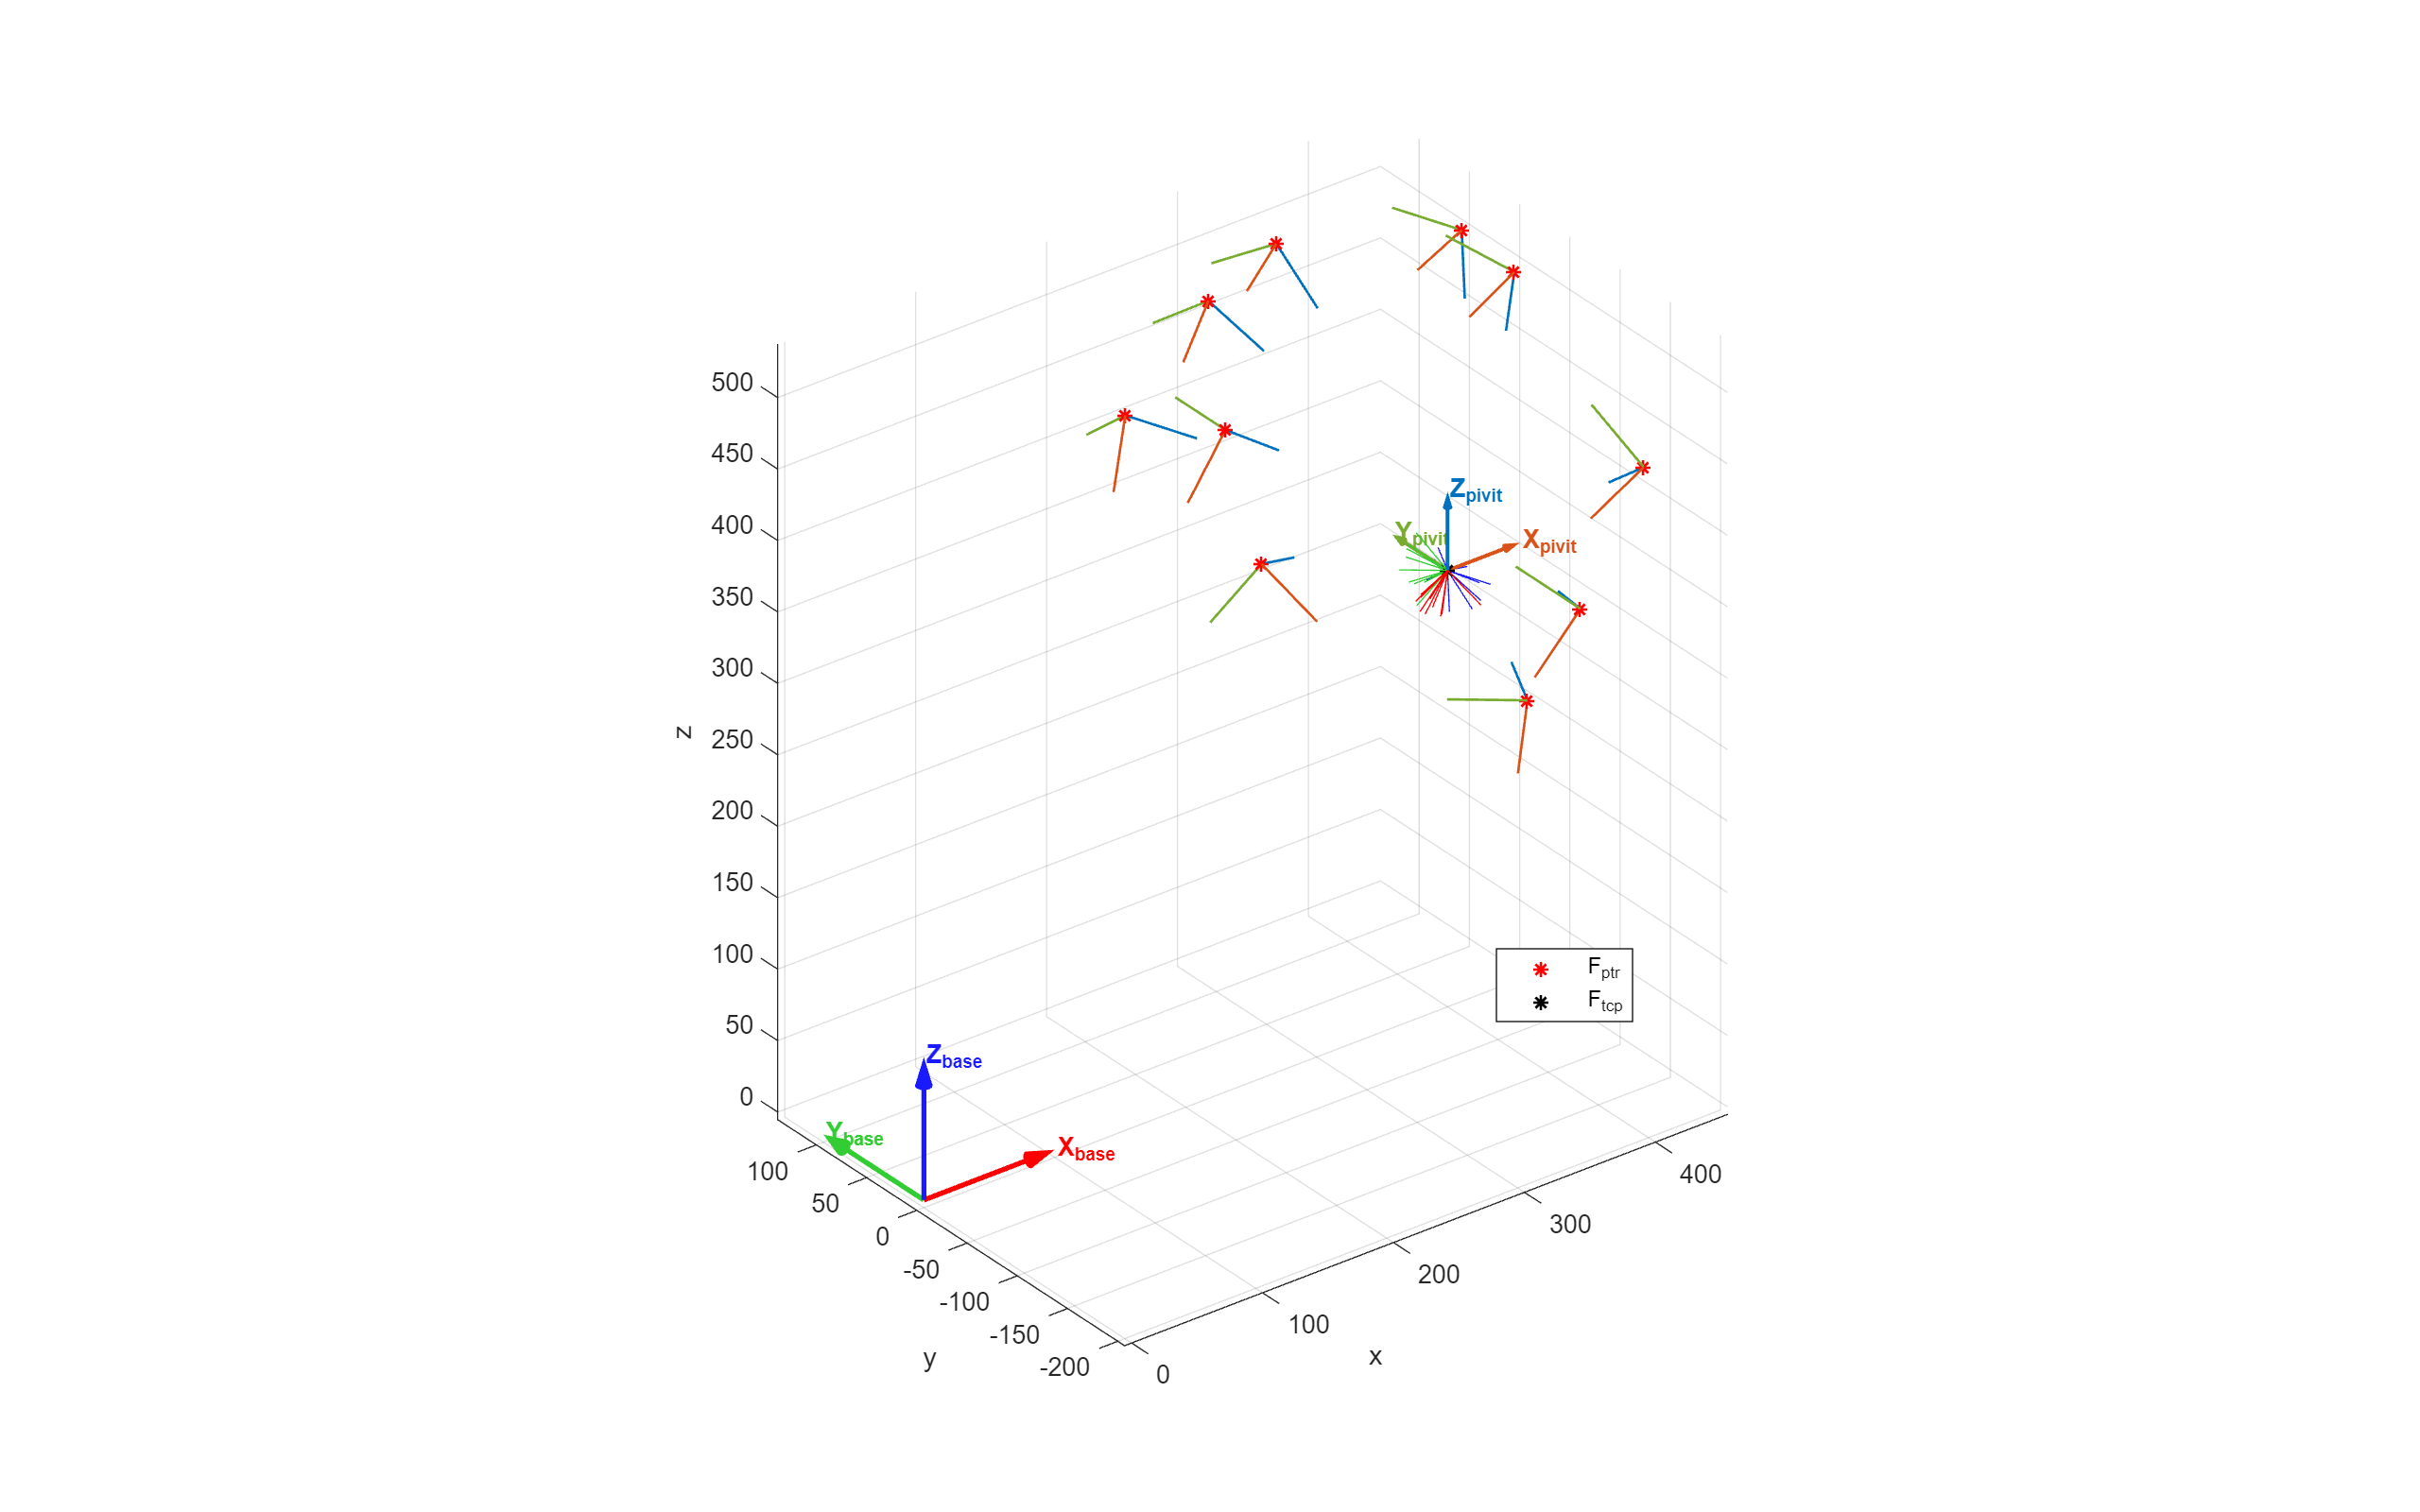

tcp = reshape(pagemtimes(Rk,b_tip),3,ptnum)+pk;
f = figure;
PlotFrame(eye(4),'scale',100,'linewidth',2,'style','-',...
    'arrowsize',1/5,'colorind',1,'text','on','frameind','_{base}');hold on
PlotFrame(R2T(eye(3),b_post'),'scale',55,'linewidth',1.5,'style','-',...
    'arrowsize',1/5,'colorind',2,'text','on','frameind','_{pivit}');hold on
for i = 1:ptnum
    PlotFrame(R2T(Rk(:,:,i),pk(:,i)),'scale',50,'linewidth',1,...
        'style','-','colorind',2,'text','off');hold on    
    PlotFrame(R2T(Rk(:,:,i),tcp(:,i)),'scale',30,'linewidth',0.5,...
        'style','-','colorind',1,'text','off');hold on        
end
pt(1) = plot3(pk(1,:),pk(2,:),pk(3,:),'*r','LineWidth',1);hold on
pt(2) = plot3(tcp(1,:),tcp(2,:),tcp(3,:),'*k','LineWidth',1);hold on
legend(pt,{'F_{ptr}','F_{tcp}'})
grid on; axis equal; xlabel('x'); ylabel('y'); zlabel('z')
set(f,'Units','normalized','Position',[0,0,1,1])
legend("Position", [0.61819,0.32438,0.05625,0.048125])